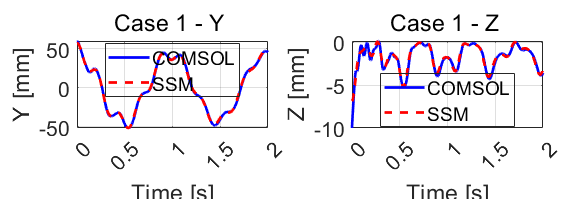

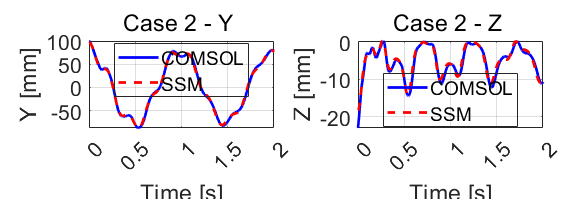

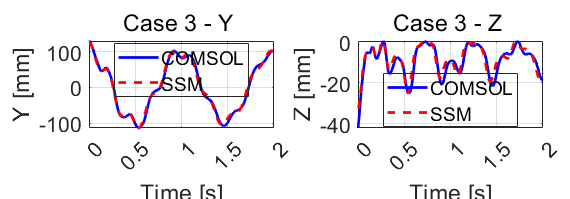

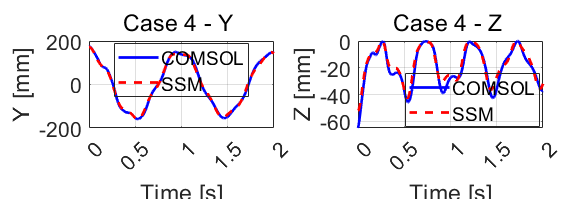

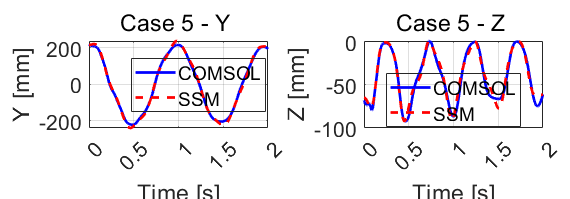

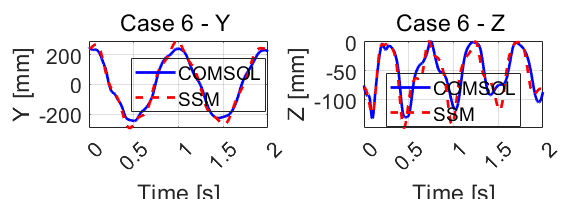

clear; clc; close all;

% ============================================================
% 参数设置
% ============================================================
num_cases = 6;
font_size = 16;
RMSE_y  = zeros(num_cases, 1);
RMSE_z  = zeros(num_cases, 1);
RMSE_yz = zeros(num_cases, 1);

case_names = cell(num_cases, 1);

% ============================================================
% 横坐标时间范围设置
% ============================================================
use_custom_xlim = true;

t_min_plot = 0;
t_max_plot = 2;     % 根据你的数据修改
dt_tick = 0.5;         % 横坐标刻度间隔

% 如果想自动使用两组数据的共同时间区间，可以改为：
% use_custom_xlim = false;


% ============================================================
% 逐组绘制 y / z 方向轨迹，并计算 RMSE
% ============================================================
for i = 1:num_cases

    case_names{i} = ['Case ', num2str(i)];

    % -----------------------------
    % 加载数据
    % -----------------------------
    comsol_file = ['comsol_save', num2str(i), '.mat'];
    ssm_file    = ['SSM_save', num2str(i), '.mat'];

    load(comsol_file);
    load(ssm_file);

    comsol_var = ['comsol_save', num2str(i)];
    ssm_var    = ['SSM_save', num2str(i)];

    comsol_data = eval(comsol_var);
    ssm_data    = eval(ssm_var);

    t_comsol = comsol_data.time(:);
    data_comsol_all = comsol_data.data;

    t_ssm = ssm_data.time(:);
    data_ssm_all = ssm_data.data;

    % -----------------------------
    % 统一数据格式为 Nt × 3
    % -----------------------------
    data_comsol_all = format_xyz_data(data_comsol_all, length(t_comsol));
    data_ssm_all    = format_xyz_data(data_ssm_all, length(t_ssm));

    % -----------------------------
    % 提取 y, z 方向
    % 假设列顺序为 x, y, z
    % -----------------------------
    y_comsol = data_comsol_all(:, 2);
    z_comsol = data_comsol_all(:, 3);

    y_ssm = data_ssm_all(:, 2);
    z_ssm = data_ssm_all(:, 3);

    % -----------------------------
    % 时间排序
    % -----------------------------
    [t_comsol, idx1] = sort(t_comsol);
    y_comsol = y_comsol(idx1);
    z_comsol = z_comsol(idx1);

    [t_ssm, idx2] = sort(t_ssm);
    y_ssm = y_ssm(idx2);
    z_ssm = z_ssm(idx2);

    % -----------------------------
    % 共同时间区间
    % -----------------------------
    t_start = max(t_comsol(1), t_ssm(1));
    t_end   = min(t_comsol(end), t_ssm(end));

    t_common = t_comsol(t_comsol >= t_start & t_comsol <= t_end);

    % -----------------------------
    % 插值到统一时间轴
    % -----------------------------
    y_comsol_c = interp1(t_comsol, y_comsol, t_common, 'linear');
    z_comsol_c = interp1(t_comsol, z_comsol, t_common, 'linear');

    y_ssm_c = interp1(t_ssm, y_ssm, t_common, 'linear');
    z_ssm_c = interp1(t_ssm, z_ssm, t_common, 'linear');

    % -----------------------------
    % 计算 RMSE
    % -----------------------------
    e_y = y_comsol_c - y_ssm_c;
    e_z = z_comsol_c - z_ssm_c;

    RMSE_y(i)  = sqrt(mean(e_y.^2));
    RMSE_z(i)  = sqrt(mean(e_z.^2));
    RMSE_yz(i) = sqrt(mean(e_y.^2 + e_z.^2));

    % ========================================================
    % 绘图：每组 y / z 两个方向横向摆放
    % ========================================================
    fig = figure('Name', ['Trajectory comparison - Case ', num2str(i)], ...
                 'Color', 'w');
    
    % 调整整个窗口大小：[左 下 宽 高]
    % 宽度大一些，高度适中，适合横向放两个子图
    set(fig, 'Position', [200, 200, 1200, 420]);
    
    % 使用 tiledlayout 控制子图布局
    tl = tiledlayout(1, 2);
    
    % 控制子图之间的间距和边缘空白
    tl.TileSpacing = 'compact';
    tl.Padding = 'compact';
    
    % -----------------------------
    % y 方向子图
    % -----------------------------
    ax1 = nexttile(1);
    plot(t_comsol, y_comsol, 'b','LineWidth', 2.0); hold on;
    plot(t_ssm, y_ssm, 'r--', 'LineWidth', 2.0);
    grid on;
  
    xlabel('Time [s]');
    ylabel('Y [mm]');
    title(['Case ', num2str(i), ' - Y ']);
    lgd1 = legend('COMSOL', 'SSM', 'Location', 'best');
    set(lgd1, 'Color', 'none');
    set(gca, 'FontSize', font_size);
    
    if use_custom_xlim
        xlim([t_min_plot, t_max_plot]);
        xticks(t_min_plot:dt_tick:t_max_plot);
    else
        xlim([t_start, t_end]);
    end
    
    % -----------------------------
    % z 方向子图
    % -----------------------------
    ax2 = nexttile(2);
    plot(t_comsol, z_comsol, 'b', 'LineWidth', 2.0); hold on;
    plot(t_ssm, z_ssm, 'r--', 'LineWidth', 2.0);
    grid on;
    
    xlabel('Time [s]');
    ylabel('Z [mm]');
    title(['Case ', num2str(i), ' - Z ']);
    lgd2 = legend('COMSOL', 'SSM', 'Location', 'best');
    set(lgd2, 'Color', 'none');
    if use_custom_xlim
        xlim([t_min_plot, t_max_plot]);
        xticks(t_min_plot:dt_tick:t_max_plot);
    else
        xlim([t_start, t_end]);
    end
    set(gca, 'FontSize', font_size);
    % ========================================================
    % 进一步微调两个子图的大小比例
    % ========================================================
    % 默认 tiledlayout 下两个子图等宽。
    % 如果希望 y 图和 z 图等宽，下面两行可以不写。
    % 如果希望左图略宽、右图略窄，可以手动改 Position。
    
    drawnow;
    
%     ax1.Position = [0.08, 0.18, 0.40, 0.68];   % [左 下 宽 高]
%     ax2.Position = [0.56, 0.18, 0.40, 0.68];   % [左 下 宽 高]

end

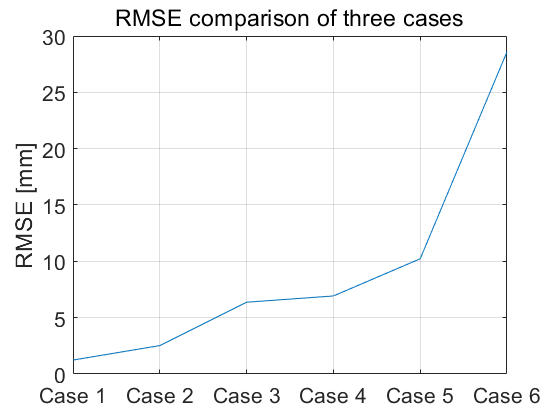



% ============================================================
% RMSE 柱状图对比
% ============================================================
figure('Name', 'RMSE comparison', 'Color', 'w');

% RMSE_mat = [RMSE_y, RMSE_z, RMSE_yz];
RMSE_mat =RMSE_yz;

plot(RMSE_mat);
grid on;

set(gca, 'XTickLabel', case_names);
% xlabel('Cases');
ylabel('RMSE [mm]');
title('RMSE comparison of three cases');

% lgd3 = legend('Y ', 'Z ', 'YZ vector error', ...
%               'Location', 'best');
% set(lgd3, 'Color', 'none');
set(gca, 'FontSize', font_size);

% ============================================================
% 打印 RMSE 结果
% ============================================================
fprintf('\n================ RMSE Results ================\n');


================ RMSE Results ================


for i = 1:num_cases
    fprintf('Case %d:\n', i);
    fprintf('  RMSE_y  = %.6e\n', RMSE_y(i));
    fprintf('  RMSE_z  = %.6e\n', RMSE_z(i));
    fprintf('  RMSE_yz = %.6e\n', RMSE_yz(i));
end

Case 1:


  RMSE_y  = 1.095877e+00


  RMSE_z  = 5.742745e-01


  RMSE_yz = 1.237230e+00


Case 2:


  RMSE_y  = 2.298332e+00


  RMSE_z  = 1.038453e+00


  RMSE_yz = 2.522045e+00


Case 3:


  RMSE_y  = 5.755286e+00


  RMSE_z  = 2.730981e+00


  RMSE_yz = 6.370366e+00


Case 4:


  RMSE_y  = 5.520233e+00


  RMSE_z  = 4.185524e+00


  RMSE_yz = 6.927596e+00


Case 5:


  RMSE_y  = 9.075514e+00


  RMSE_z  = 4.718340e+00


  RMSE_yz = 1.022877e+01


Case 6:


  RMSE_y  = 2.476166e+01


  RMSE_z  = 1.431648e+01


  RMSE_yz = 2.860247e+01


fprintf('==============================================\n');



% ============================================================
% 局部函数：统一 xyz 数据格式为 Nt × 3
% ============================================================

function data_xyz = format_xyz_data(data_raw, Nt)

    [m, n] = size(data_raw);

    if m == Nt && n >= 3
        % 数据格式为 Nt × 3
        data_xyz = data_raw(:, 1:3);

    elseif n == Nt && m >= 3
        % 数据格式为 3 × Nt
        data_xyz = data_raw(1:3, :).';

    elseif numel(data_raw) == 3 * Nt
        % 数据是长向量，尝试 reshape 为 Nt × 3
        data_xyz = reshape(data_raw(:), [], 3);

    else
        error('无法识别数据格式，请检查 data 的尺寸。');
    end

end